% Method of Characteristics for Minimum Length Supersonic Nozzle
% Created by Jason Chen, Project Caelus
% Thomas Jefferson High School for Science and Technology
% Developed on December 31st, 2018

% This program generates a minimum-length supersonic diverging nozzle 
% contour using the Method of Characteristics. Equations and methods are 
% derived from the von Karman Institute's 'Aerothermodynamics of High 
% Speed Flows, Lecture 5'. References in any comments throughout this code
% to equations or pages are based on the lecture's slideshow.

% Outputs an Excel file of all (x,y) points that define the nozzle contour,
% including the throat, named moc_data.xlsx. Also outputs a PDF file
% displaying the nozzle contour.

clc; close all; clear; tic;

## Inputs

Processes user inputs and defines calculation variables.

fprintf('Input rocket parameters or specify Cp/Cv, Mach, and Rt? \n');

Input rocket parameters or specify Cp/Cv, Mach, and Rt? 


option = input('Enter ROCKET or MACH: ', 's');
if (strcmp(option,'ROCKET')) % If user inputs ROCKET
    F = input('Desired thrust (N): ');
    P0 = input('Chamber pressure (Pa): ');
    ALT = input('Altitude (m): ');
    T0 = input('Combustion chamber temperature (K): ');
    M = input('Gas molecular mass (kg/mol): ');
    gamma = input('Ratio of specific heats (Cp/Cv): ');
    n = input('Number of characteristics (>2) emanating from throat: ');
    P3 = exitPressure(ALT); % Calculate exit pressure
    [Mnum2,Rt] = solveIsentropic(F,P0,P3,T0,M,gamma); % Solve isentropic parameters
elseif (strcmp(option,'MACH')) % If user inputs MACH
    Mnum2 = input('Exit Mach number: ');
    gamma = input('Ratio of specific heats (Cp/Cv): ');
    Rt = input('Throat radius (mm): ');
    n = input('Number of characteristics (>2) emanating from throat: ');
else
    fprintf('Please enter either ROCKET or MACH. \n');
end

## Calculate Expansion Waves

theta_max = (1/2)*PMfunct(Mnum2, gamma); % Maximum wall angle in degrees
theta_0 = theta_max/n; % First flow deflection angle is delta theta, i.e. theta interval
node = (1/2)*n*(4+n-1); % Computes total nodes (intersections) that need to be characterized
pointnum = n+1; % Number of points that will define the nozzle shape (including throat)
points = zeros(pointnum, 2); % Pre-allocates a matrix of zeros for the (x,y) export points
points(1, 1:2) = [0 Rt]; % First coordinate

[v,KL,KR,theta] = solveParams(theta_max,theta_0,n);
[Mach,mu] = solveMachs(v,n);

## Plot Expansion Waves

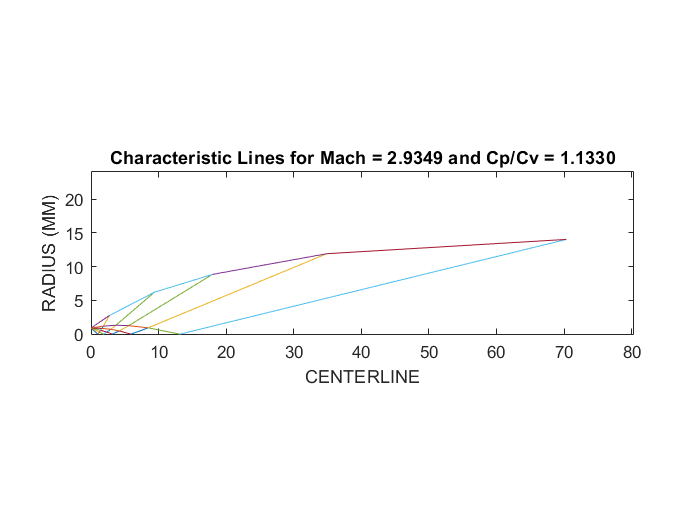

i=1;
count=2; % Index counter for the points matrix; starts at 2 since index 1 is already used
x=zeros(1,node); % Pre-allocates an array for x-coordinates
y=zeros(1,node); % Pre-allocates an array for y-coordinates
wall=theta_max;
while (i<=n+1) % Iterates through the first expansion wave and its reflection
    if (i==1) % Initial incident expansion wave from the throat
        x(i)=-Rt/(tand(theta(i)-mu(i))); % Slope of (RR) characteristics, Slide 33
        y(i)=0;
        plot([0 x(i)],[Rt 0]); % Connecting and plotting the throat and Point 1 (Slide 38)
        hold on 
    elseif (i==n+1) % Reflected wave intersection with the wall
        % Intersection at the wall is defined as the intersection of a line
        % with slope tan(theta_max) and the LR characteristic from the last
        % last point on the reflected wave (Slide 38).
        x(i)=(y(i-1)-Rt-x(i-1)*tand((theta(i-1)+theta(i)+mu(i-1)+mu(i))*0.5))/... % Slide 23
        (tand(0.5*(wall+theta(i)))-tand((theta(i-1)+theta(i)+mu(i-1)+mu(i))*0.5));
        y(i)=Rt+x(i)*tand(0.5*(wall+theta(i))); % Slide 23
        points(count, 1:2) = [x(i) y(i)]; % Adds the (x,y) wall coordinate to points
        count=count+1; % Updates count
        plot([x(i-1) x(i)],[y(i-1) y(i)]);
        hold on
        plot([0 x(i)],[Rt y(i)]);
        hold on
    else % Reflected wave
        x(i)=(Rt-y(i-1)+x(i-1)*tand(0.5*(mu(i-1)+theta(i-1)+mu(i)+theta(i))))/...
        (tand(0.5*(mu(i-1)+theta(i-1)+mu(i)+theta(i)))-tand(theta(i)-mu(i)));
        y(i)=tand(theta(i)-mu(i))*x(i)+Rt;
        plot([x(i-1) x(i)],[y(i-1) y(i)]);
        hold on
        plot([0 x(i)],[Rt y(i)]);
        hold  on
    end
    i=i+1;
    hold on
end
h=i;
k=0;
i=h;
for j=1:n-1
    while (i<=h+n-k-1)
        if (i==h)
            x(i)=x(i-n+k)-y(i-n+k)/(tand(0.5*(theta(i-n+k)+theta(i)-mu(i-n+k)-mu(i))));
            y(i)=0;
            plot([x(i-n+k) x(i)],[y(i-n+k) y(i)]);
            hold on
        elseif (i==h+n-k-1)
            x(i)=(x(i-n+k)*tand(0.5*(theta(i-n+k)+theta(i)))-y(i-n+k)+y(i-1)-x(i-1)*...
            tand((theta(i-1)+theta(i)+mu(i-1)+mu(i))*0.5))/...
            (tand(0.5*(theta(i-n+k)+theta(i)))-tand((theta(i-1)+theta(i)+mu(i-1)+mu(i))*0.5));
            y(i)=y(i-n+k)+(x(i)-x(i-n+k))*tand(0.5*(theta(i-n+k)+theta(i)));
            points(count, 1:2) = [x(i) y(i)]; % Adds the (x,y) wall coordinate to points
            count=count+1; % Updates count
            plot([x(i-1) x(i)],[y(i-1) y(i)]);
            hold on
            plot([x(i-n+k) x(i)],[y(i-n+k) y(i)]);
            hold on
        else
            s1= tand(0.5*(theta(i)+theta(i-1)+mu(i)+mu(i-1)));
            s2= tand(0.5*(theta(i)+theta(i-n+k)-mu(i)-mu(i-n+k)));
            x(i)=(y(i-n+k)-y(i-1)+s1*x(i-1)-s2*x(i-n+k))/(s1-s2);
            y(i)=y(i-1)+(x(i)-x(i-1))*s1;
            plot([x(i-1) x(i)],[y(i-1) y(i)]);
            hold on
            plot([x(i-n+k) x(i)],[y(i-n+k) y(i)]);
            hold on
        end
        i=i+1;
    end
    k=k+1;
    h=i;
    i=h;
    hold on
end
title(sprintf('Characteristic Lines for Mach = %.4f and Cp/Cv = %.4f',Mnum2,gamma))
xlabel('CENTERLINE')
ylabel('RADIUS (MM)')
axis equal
xlim([0 x(node)+10])
ylim([0 y(node)+10])

## Export

Exports Figure 1 (nozzle contour) as a PNG and points() as a text file.

saveas(gcf, 'MOC_contour.pdf'); % Exports as PDF

filename='moc_data.xlsx'; % Defines Excel file name
xlswrite(filename, points); % Writes points() to the specified file
toc % Prints time elapsed during code execution

Elapsed time is 30.343249 seconds.


## Exit Pressure

function P3 = exitPressure(ALT)
if (ALT >= 25000)  % Upper Stratosphere
    T = -131.21 + 0.00299 * ALT;
    P3 = (2.488 * ((T + 273.1) / 216.6)^(-11.388))*1000;
elseif (11000 < ALT) && (ALT < 25000)  % Lower Stratosphere
    T = -56.46;
    P3 = (22.65 * exp(1.73 - 0.000157 * ALT))*1000;
else % Troposphere
    T = 15.04 - 0.00649 * ALT;
    P3 = (101.29 * ((T + 273.1) / 288.08)^(5.256))*1000;
end
end

## Isentropic Flow Relations

function [Mnum2,Rt] = solveIsentropic(F,P0,P3,T0,M,k)
PR = P3/P0; % Pressure ratio
TR = PR^((k-1)/k); % Temperature ratio
R = (8314.3/M); % Gas constant
CTt = (2*k*R*T0)/(k-1); % Critical throat temperature (disputed equation?)
CTp = ((2/(k+1))^(k/(k-1)))*P0; % Critical throat pressure
CTv = sqrt((2*k*R*T0)/(k+1)); % Critical throat velocity
v2 = sqrt((CTt)*(1-TR)); % Exit velocity
mdot = F/v2; % Mass flow rate
T2 = T0*TR; % Exit temperature
a2 = sqrt(k*R*T2); % Exit speed of sound
Mnum2 = v2/a2; % Exit Mach number
At = (mdot*(sqrt(k*R*T0))) / (k*P0*(sqrt(((2/(k+1)) ^ ((k+1)/(k-1)))))); % Throat area
Rt = sqrt(At / pi)*1000; % Throat radius in mm
end

## Characteristic Parameter Solver

v = Prandtl-Meyer angle KL = Left-running characteristic constant KR = Right-running characteristic constant theta = Flow angle relative to horizontal

function [v,KL,KR,theta] = solveParams(theta_max,theta_0,n)

dtheta = (theta_max - theta_0)/(n-1); % Theta interval
node = (1/2)*n*(4+n-1);
v = zeros(1,node); % Pre-allocates a matrix of zeros for PM angles
KL = zeros(1,node);
KR = zeros(1,node);
theta = zeros(1,node);
% Test case used: solveParams(25.8276, 2.5828, 7)
for i=1:n % Increments through all points emanating directly from the throat
    theta(i)=theta_0+(i-1)*dtheta;
    v(i)=theta(i);
    KL(i)=theta(i)-v(i); % Slide 20, s+ characteristic constant
    KR(i)=theta(i)+v(i); % Slide 20, s- characteristic constant
end
i=n+1; % i=8, referring to the test case of n=7
theta(i)=theta(i-1); % Makes a copy of the last set of parameters which are indexed as i-1
v(i)=v(i-1);
KL(i)=KL(i-1);
KR(i)=KR(i-1);
p=2;
q=n+2; % q=9
for k=1:n-1
    j=p; % j=2 (on the first iteration of this for-loop)
    h=q; % h=9, parameters with an index of 9 refers to Point 2 (on Slide 36)
    theta(h)=0; % Flow angle is canceled out after it crosses an incident and then its reflected wave
    KR(h)=KR(j); % The right-running (RR) characteristic of Point 2 (on Slide 36) is the same as the 
    % RR characteristic of Point 9 on the centerline
    v(h)=KR(j)-theta(h); % Slide 20, RR characteristic constant equation rearranged
    KL(h)=theta(h)-v(h); % Slide 20, LR characteristic constant equation
    j=j+1; % j=3
    for i=h+1:n-p+q % Runs through all intersections between the current reflected wave and any
        % incident waves it encounters, i=10, goes to i=14 (Points 3 through 7)
        KR(i)=KR(j); % The RR characteristic of Point 3 (on Slide 36) is the same as the 
        % RR characteristic of Point 16 on the centerline
        KL(i)=KL(i-1); % The LR characteristic of Point 3 is the same as the LR
        % characteristic of Point 2, KL(10) = KL of Point 3
        theta(i)=0.5*(KL(i)+KR(i)); % Slide 20, flow angle equation
        v(i)=0.5*(KR(i)-KL(i)); % Slide 20, PM angle equation
        j=j+1; % j is now pointing at the fourth element, j=4, goes to j=8 by the end of the loop
    end
    if i==n-p+q % Only true on the first pass of the main for-loop
        h=i+1; % h=15
    else
        h=h+1;
    end
    theta(h)=theta(h-1); % Makes a copy of the last set of parameters which are indexed as h-1
    % These parameters with index h refer to the point at the intersection
    % with the wall (Point 8 on Slide 38) and have equivalent properties as
    % the last point on the reflected wave before it (which is indexed as
    % h-1, i.e. Point 7 on Slide 38).
    v(h)=v(h-1);
    KL(h)=KL(h-1);
    KR(h)=KR(h-1);
    p=p+1; % p=3, pointing at the next (third) centerline point (Point 16 on Slide 36) 
    q=h+1; % q=16, pointing at the next point of intersection between the second
    % reflected wave and the third incident wave (Point 10 on Slide 41)
end
end

## Mach Parameter Solver

Input is the array of Prandtl-Meyer angles produced by solveParams() Returns an array of local Mach numbers, Mach, and local Mach angles, mu

function [Mach,mu] = solveMachs(v,n)
node = (1/2)*n*(4+n-1);
Mach = zeros(1,node); % Pre-allocates a matrix of zeros for local Mach numbers
mu = zeros(1,node); % Pre-allocates a matrix of zeros for local Mach angles
for i=1:node
    Mach(i)=invPMfunct(v(i)); % Inverse Prandtl-Meyer function
    mu(i)=Mu(Mach(i)); % Computes the local Mach angles, using Mu()
end
end

## Prandtl-Meyer Function

Input is the local Mach number, dimensionless Returns the Prandtl-Meyer angle, in degrees

function v = PMfunct(mach, gamma) % Slide 20, Prandtl-Meyer function
sect1 = (gamma+1)/(gamma-1);
sect2 = (gamma-1)/(gamma+1);
sect3 = (mach^2)-1;
v = rad2deg(sqrt(sect1)*atan(sqrt(sect2*sect3)) - atan(sqrt(sect3)));
end

## Inverse Prandtl-Meyer Function

Input is the Prandtl-Meyer angle, in degrees Returns the local Mach number, dimensionless

function mach = invPMfunct(v)
A = 1.3604; % Pre-formulated coefficients
B = 0.0962;
C = -0.5127;
D = -0.6722;
E = -0.3278;
v = deg2rad(v); % Converts the inputed angle in degrees to radians
v_0 = (pi/2)*(sqrt(6)-1);
y = (v/v_0)^(2/3);
mach = (1 + A*y + B*(y^2) + C*(y^3))/(1 + D*y + E*(y^2));
end

## Mach Line Angle Function

Input is the local Mach number, dimensionless Returns the Mach line angle, in degrees

function mu=Mu(M)
mu=asind(1/M); % Slide 20, Mach angle
end